# Lab7

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgs_dataset = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd_dataset = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
higgs_pt = higgs_dataset(1,:);
higgs_eta = higgs_dataset(2,:);
higgs_phi = higgs_dataset(3,:);
higgs_mass = higgs_dataset(4,:);
higgs_ee2 = higgs_dataset(5,:);
higgs_ee3 = higgs_dataset(6,:);
higgs_d2 = higgs_dataset(7,:);
higgs_angularity = higgs_dataset(8,:);
higgs_t1 = higgs_dataset(9,:);
higgs_t2 = higgs_dataset(10,:);
higgs_t3 = higgs_dataset(11,:);
higgs_t21 = higgs_dataset(12,:);
higgs_t32 = higgs_dataset(13,:);
higgs_KtDeltaR = higgs_dataset(14,:);
qcd_pt = qcd_dataset(1,:);
qcd_eta = qcd_dataset(2,:);
qcd_phi = qcd_dataset(3,:);
qcd_mass = qcd_dataset(4,:);
qcd_ee2 = qcd_dataset(5,:);
qcd_ee3 = qcd_dataset(6,:);
qcd_d2 = qcd_dataset(7,:);
qcd_angularity = qcd_dataset(8,:);
qcd_t1 = qcd_dataset(9,:);
qcd_t2 = qcd_dataset(10,:);
qcd_t3 = qcd_dataset(11,:);
qcd_t21 = qcd_dataset(12,:);
qcd_t32 = qcd_dataset(13,:);
qcd_KtDeltaR = qcd_dataset(14,:);


In lab 7 we focus on event selection optimization, I pick high pT (transverse momentum) samples for this lab. I use the dedicated training samples for event selection optimization. All my studies are carried out by normalizing Higgs and QCD samples in high pT sample to given expected yields accordingly.

First, I made a stacked normalized histogram plot for the mass of qcd and higgs. The histogram shows the Higgs boson has a mass around 125 GeV and qcd is spread out around 120 GeV. 

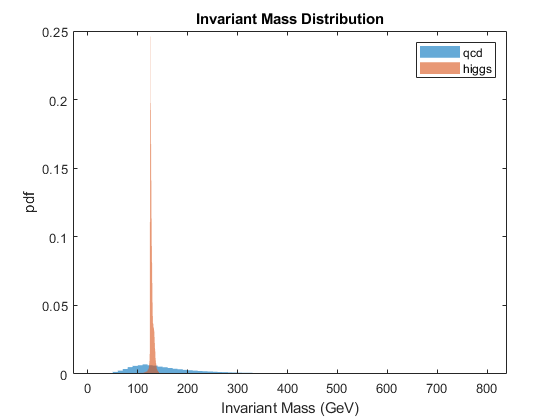

figure;
histogram(qcd_mass,"EdgeColor","none","Normalization","pdf")
title("Invariant Mass Distribution");
hold on;
histogram(higgs_mass,"EdgeColor","none","Normalization","pdf")
xlabel("Invariant Mass (GeV)"); 
ylabel("pdf");
legend("qcd","higgs");
hold off

I was given with expected yield for N higgs and N qcd, so I can calculate the significance  NHiggs/(√NQCD). Which is 1.1180. 

N_higgs = 50;
N_qcd = 2000;
Significance = N_higgs/ sqrt(N_qcd)

Significance = 1.1180

In order to identify mass cuts to optimize the expected significance I need to find the spot the can maximizes the chance to find the signal.

First, I will try different mass cuts systematically.

As the histogram shows the Higgs boson has a mass around 125 GeV, so picked range of values around 125

N_higgs_tot = length(higgs_mass);
N_qcd_tot = length(qcd_mass);
top_cut = 150;
bot_cut = 100;
qcd_mass(qcd_mass<=bot_cut)=[]; 
qcd_mass(qcd_mass>top_cut)=[];
N_qcd2=length(qcd_mass)*N_qcd/N_qcd_tot;
higgs_mass(higgs_mass<=bot_cut)=[]; 
higgs_mass(higgs_mass>top_cut)=[];
N_higgs2=length(higgs_mass)*N_higgs/N_higgs_tot;
Significance1 = N_higgs2/ sqrt(N_qcd2);
top_cut2 = 140;
bot_cut2 = 110;
qcd_mass(qcd_mass<=bot_cut2)=[]; 
qcd_mass(qcd_mass>top_cut2)=[];
N_qcd2=length(qcd_mass)*N_qcd/N_qcd_tot;
higgs_mass(higgs_mass<=bot_cut2)=[]; 
higgs_mass(higgs_mass>top_cut2)=[];
N_higgs2=length(higgs_mass)*N_higgs/N_higgs_tot;
Significance2 = N_higgs2/ sqrt(N_qcd2);
top_cut3 = 130;
bot_cut3 = 120;
qcd_mass(qcd_mass<=bot_cut3)=[]; 
qcd_mass(qcd_mass>top_cut3)=[];
N_qcd2=length(qcd_mass)*N_qcd/N_qcd_tot;
higgs_mass(higgs_mass<=bot_cut3)=[]; 
higgs_mass(higgs_mass>top_cut3)=[];
N_higgs2=length(higgs_mass)*N_higgs/N_higgs_tot;
Significance3 = N_higgs2/ sqrt(N_qcd2);
top_cut4 = 128;
bot_cut4 = 122;
qcd_mass(qcd_mass<=bot_cut4)=[]; 
qcd_mass(qcd_mass>top_cut4)=[];
N_qcd2=length(qcd_mass)*N_qcd/N_qcd_tot;
higgs_mass(higgs_mass<=bot_cut4)=[]; 
higgs_mass(higgs_mass>top_cut4)=[];
N_higgs2=length(higgs_mass)*N_higgs/N_higgs_tot;
Significance4 = N_higgs2/ sqrt(N_qcd2);
top_cut5 = 127;
bot_cut5 = 123;
qcd_mass(qcd_mass<=bot_cut5)=[]; 
qcd_mass(qcd_mass>top_cut5)=[];
N_qcd2=length(qcd_mass)*N_qcd/N_qcd_tot;
higgs_mass(higgs_mass<=bot_cut5)=[]; 
higgs_mass(higgs_mass>top_cut5)=[];
N_higgs2=length(higgs_mass)*N_higgs/N_higgs_tot;
Significance5 = N_higgs2/ sqrt(N_qcd2);
disp("If the cut is between "+ bot_cut + " and " + top_cut + " the significance would be " + Significance1)

If the cut is between 100 and 150 the significance would be 1.9591


disp("If the cut is between "+ bot_cut2 + " and " + top_cut2 + " the significance would be " + Significance2)

If the cut is between 110 and 140 the significance would be 2.4463


disp("If the cut is between "+ bot_cut3 + " and " + top_cut3 + " the significance would be " + Significance3)

If the cut is between 120 and 130 the significance would be 3.3475


disp("If the cut is between "+ bot_cut4 + " and " + top_cut4 + " the significance would be " + Significance4)

If the cut is between 122 and 128 the significance would be 3.4463


disp("If the cut is between "+ bot_cut5 + " and " + top_cut5 + " the significance would be " + Significance5)

If the cut is between 123 and 127 the significance would be 3.3217


As shows above the set of the mass cuts which give me the highest significance is between 122 and 128.The significance would be 3.4463

Next I will make stacked histogram plots for the reset of features

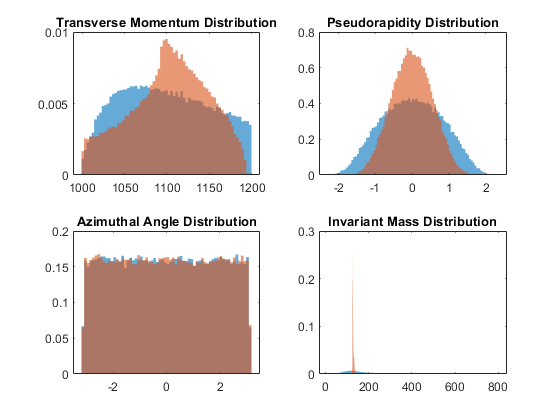

figure;
for k = 1:4
    subplot(2,2,k);
    histogram(qcd_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(higgs_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold off;
end
subplot(2,2,1);
title("Transverse Momentum Distribution");
subplot(2,2,2);
title("Pseudorapidity Distribution");
subplot(2,2,3);
title("Azimuthal Angle Distribution");
subplot(2,2,4);
title("Invariant Mass Distribution");

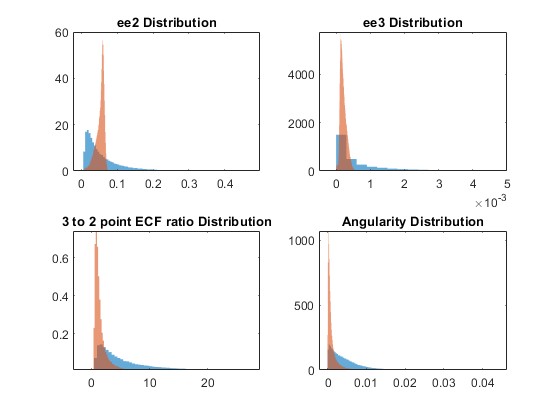

figure;
for k = 5:8
    subplot(2,2,k-4);
    histogram(qcd_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(higgs_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold off;
end
subplot(2,2,1)
title("ee2 Distribution");
subplot(2,2,2)
title("ee3 Distribution");
xlim([-0.0005 0.0050])
ylim([0 5744])
subplot(2,2,3)
title("3 to 2 point ECF ratio Distribution");
xlim([-3.1 28.9])
ylim([0.01 0.74])
subplot(2,2,4)
title('Angularity Distribution')

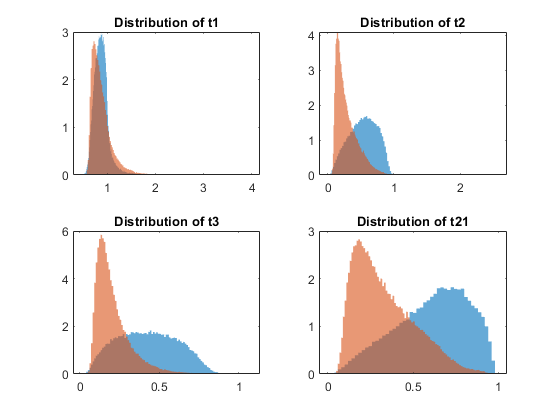

figure;
for k = 9:12
    subplot(2,2,k-8);
    histogram(qcd_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(higgs_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold off;
end
subplot(2,2,1);
title('Distribution of t1')
subplot(2,2,2);
title('Distribution of t2')
subplot(2,2,3);
title('Distribution of t3')
subplot(2,2,4);
title('Distribution of t21')

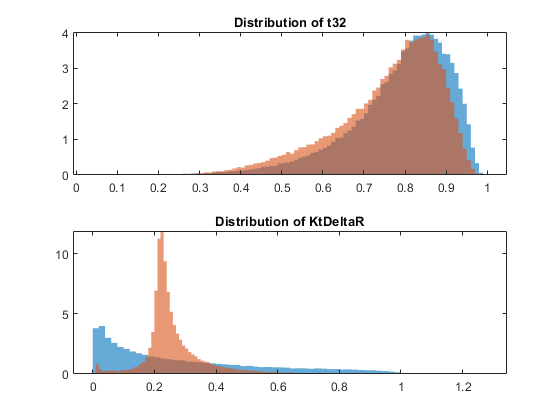

figure;
for k = 13:14
    subplot(2,1,k-12);
    histogram(qcd_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(higgs_dataset(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold off;
end
subplot(2,1,1);
title('Distribution of t32')
subplot(2,1,2);
title('Distribution of KtDeltaR')

I think events like Distribution of t3, Pseudorapidity Distribution, ee2 Distribution, ee3 Distribution, and Distribution of KtDeltaR will have higher significance after feature cut. Since there are place without overlay between signal and background, and some place with low signal with high background. 

Next, I will try to optimal mass cuts for Distribution of t3 

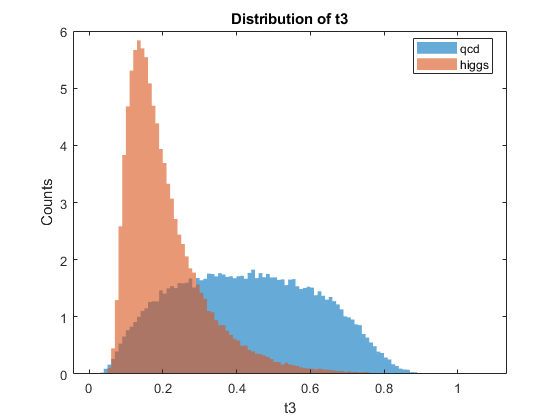

figure;
histogram(qcd_t3,"EdgeColor",'none',"Normalization","pdf")
hold on
histogram(higgs_t3,"EdgeColor",'none',"Normalization","pdf")
legend('qcd','higgs','Location','best')
title('Distribution of t3')
ylabel('Counts')
xlabel('t3')

N_higgs_tot = length(higgs_t3);
N_qcd_tot = length(qcd_t3);
top_cut = 0.8;
bot_cut = 0.05;
qcd_t3(qcd_t3<=bot_cut)=[]; 
qcd_t3(qcd_t3>top_cut)=[];
N_t3qcd2=length(qcd_t3)*N_qcd/N_qcd_tot;
higgs_t3(higgs_t3<=bot_cut)=[]; 
higgs_t3(higgs_t3>top_cut)=[];
N_t3higgs2=length(higgs_t3)*N_higgs/N_higgs_tot;
Significance1 = N_t3higgs2/ sqrt(N_t3qcd2);
top_cut2 = 0.4;
bot_cut2 = 0.05;
qcd_t3(qcd_t3<=bot_cut2)=[]; 
qcd_t3(qcd_t3>top_cut2)=[];
N_t3qcd2=length(qcd_t3)*N_qcd/N_qcd_tot;
higgs_t3(higgs_t3<=bot_cut2)=[]; 
higgs_t3(higgs_t3>top_cut2)=[];
N_t3higgs2=length(higgs_t3)*N_higgs/N_higgs_tot;
Significance2 = N_t3higgs2/ sqrt(N_t3qcd2);
top_cut3 = 0.2;
bot_cut3 = 0.05;
qcd_t3(qcd_t3<=bot_cut3)=[]; 
qcd_t3(qcd_t3>top_cut3)=[];
N_t3qcd2=length(qcd_t3)*N_qcd/N_qcd_tot;
higgs_t3(higgs_t3<=bot_cut3)=[]; 
higgs_t3(higgs_t3>top_cut3)=[];
N_t3higgs2=length(higgs_t3)*N_higgs/N_higgs_tot;
Significance3 = N_t3higgs2/ sqrt(N_t3qcd2);
top_cut4 = 0.18;
bot_cut4 = 0.05;
qcd_t3(qcd_t3<=bot_cut4)=[]; 
qcd_t3(qcd_t3>top_cut4)=[];
N_t3qcd2=length(qcd_t3)*N_qcd/N_qcd_tot;
higgs_t3(higgs_t3<=bot_cut4)=[]; 
higgs_t3(higgs_t3>top_cut4)=[];
N_t3higgs2=length(higgs_t3)*N_higgs/N_higgs_tot;
Significance4 = N_t3higgs2/ sqrt(N_t3qcd2);
disp("If the cut is between "+ bot_cut + " and " + top_cut + " the significance would be " + Significance1)

If the cut is between 0.05 and 0.8 the significance would be 1.125


disp("If the cut is between "+ bot_cut2 + " and " + top_cut2 + " the significance would be " + Significance2)

If the cut is between 0.05 and 0.4 the significance would be 1.5453


disp("If the cut is between "+ bot_cut3 + " and " + top_cut3 + " the significance would be " + Significance3)

If the cut is between 0.05 and 0.2 the significance would be 1.8303


disp("If the cut is between "+ bot_cut4 + " and " + top_cut4 + " the significance would be " + Significance4)

If the cut is between 0.05 and 0.18 the significance would be 1.7691


The optimal mass cuts for Distribution of t3 is between 0.05 and 0.2 with significance 1.8303.

Lab 8. Pseudo-experiment data analysis Using my optimized event selection, hunt for the signal by using one of the pseduo-experiment datasets. 

I will choose distribution of ee2 of the observed data from my high pT sample to perform the analysis.

h5disp("data_highLumi_pt_1000_1200.h5"); 

HDF5 data_highLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribut

h5disp("data_lowLumi_pt_1000_1200.h5");

HDF5 data_lowLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribute

high=h5read("data_highLumi_pt_1000_1200.h5", '/data/block0_values');
low=h5read("data_lowLumi_pt_1000_1200.h5", '/data/block0_values');

for high luminosity data of the distribution of the ee2.

First, I plot observed data, overlap with expected signal and background of ee2 without event selection.

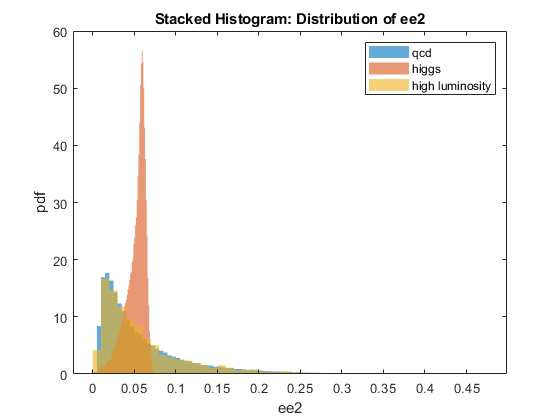

hee2=high(5,:);
figure;
histogram(qcd_ee2,"EdgeColor",'none',"Normalization","pdf");
hold on
histogram(higgs_ee2,"EdgeColor",'none',"Normalization","pdf");
histogram(hee2,"EdgeColor",'none',"Normalization","pdf");
legend('qcd','higgs','high luminosity')
title('Stacked Histogram: Distribution of ee2')
ylabel('pdf')
xlabel('ee2')

From the histogram I think the high luminosity follow the pattern of the background not the higgs signal.

next find the optimal event then plot the data with the optimal event. 

N_higgs_tot = length(higgs_ee2);
N_qcd_tot = length(qcd_ee2);

top_cut = 0.069;
bot_cut = 0.045;
qcd_ee2(qcd_ee2<=bot_cut)=[]; 
qcd_ee2(qcd_ee2>top_cut)=[];
N_ee2qcd2=length(qcd_ee2)*N_qcd/N_qcd_tot;
higgs_ee2(higgs_ee2<=bot_cut)=[]; 
higgs_ee2(higgs_ee2>top_cut)=[];
N_ee2higgs2=length(higgs_ee2)*N_higgs/N_higgs_tot;
Significance1 = N_ee2higgs2/ sqrt(N_ee2qcd2);
top_cut2 = 0.069;
bot_cut2 = 0.05;
qcd_ee2(qcd_ee2<=bot_cut2)=[]; 
qcd_ee2(qcd_ee2>top_cut2)=[];
N_ee2qcd2=length(qcd_ee2)*N_qcd/N_qcd_tot;
higgs_ee2(higgs_ee2<=bot_cut2)=[]; 
higgs_ee2(higgs_ee2>top_cut2)=[];
N_ee2higgs2=length(higgs_ee2)*N_higgs/N_higgs_tot;
Significance2 = N_ee2higgs2/ sqrt(N_ee2qcd2);
top_cut3 = 0.069;
bot_cut3 = 0.055;
qcd_ee2(qcd_ee2<=bot_cut3)=[]; 
qcd_ee2(qcd_ee2>top_cut3)=[];
N_ee2qcd2=length(qcd_ee2)*N_qcd/N_qcd_tot;
higgs_ee2(higgs_ee2<=bot_cut3)=[]; 
higgs_ee2(higgs_ee2>top_cut3)=[];
N_ee2higgs2=length(higgs_ee2)*N_higgs/N_higgs_tot;
Significance3 = N_ee2higgs2/ sqrt(N_ee2qcd2);
disp("If the cut is between "+ bot_cut + " and " + top_cut + " the significance would be " + Significance1)

If the cut is between 0.045 and 0.069 the significance would be 2.0975


disp("If the cut is between "+ bot_cut2 + " and " + top_cut2 + " the significance would be " + Significance2)

If the cut is between 0.05 and 0.069 the significance would be 2.1134


disp("If the cut is between "+ bot_cut3 + " and " + top_cut3 + " the significance would be " + Significance3)

If the cut is between 0.055 and 0.069 the significance would be 1.9772


I found the distribution of ee2 will be optimal if the cut is between 0.05 and 0.069. The significance would be 2.1134 after the cut. It is higher than the expected which is 1.118

Next, I plot the data with the optimal event. 

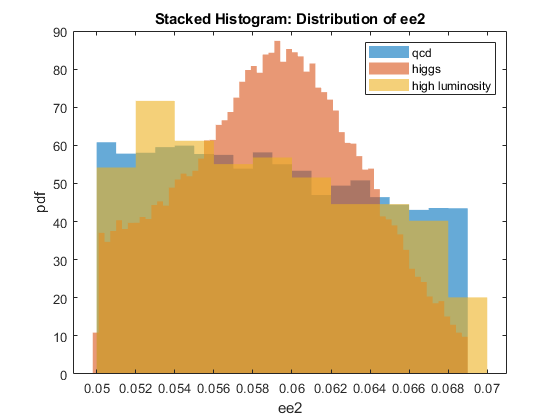

hee2=high(5,:);
hee2(hee2<=bot_cut2)=[];
hee2(hee2>top_cut2)=[];

qcd_ee2 = qcd_dataset(5,:);
qcd_ee2(qcd_ee2<=bot_cut2)=[];
qcd_ee2(qcd_ee2>top_cut2)=[];

higgs_ee2 = higgs_dataset(5,:);
higgs_ee2(higgs_ee2<=bot_cut2)=[];
higgs_ee2(higgs_ee2>top_cut2)=[];

figure;
histogram(qcd_ee2,"EdgeColor",'none',"Normalization","pdf");
hold on
histogram(higgs_ee2,"EdgeColor",'none',"Normalization","pdf");
histogram(hee2,"EdgeColor",'none',"Normalization","pdf");
legend('qcd','higgs','high luminosity')
title('Stacked Histogram: Distribution of ee2')
ylabel('pdf')
xlabel('ee2')

For low luminosity data of the distribution of the ee2.

First, I plot observed data, overlap with expected signal and background of ee2 without event selection.

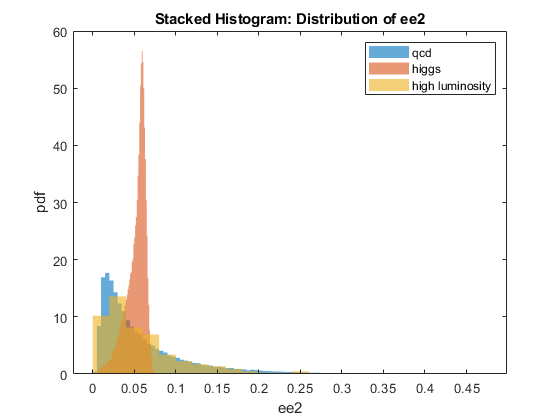

lee2=low(5,:);
qcd_ee2 = qcd_dataset(5,:);
higgs_ee2 = higgs_dataset(5,:);
figure;
histogram(qcd_ee2,"EdgeColor",'none',"Normalization","pdf");
hold on
histogram(higgs_ee2,"EdgeColor",'none',"Normalization","pdf");
histogram(lee2,"EdgeColor",'none',"Normalization","pdf");
legend('qcd','higgs','high luminosity')
title('Stacked Histogram: Distribution of ee2')
ylabel('pdf')
xlabel('ee2')

Since the signal and background has not changed the optimal event selection is the same with the high luminosity .

I found the distribution of ee2 will be optimal if the cut is between 0.05 and 0.069. The significance would be 2.1134 after the cut. It is higher than the expected which is 1.118

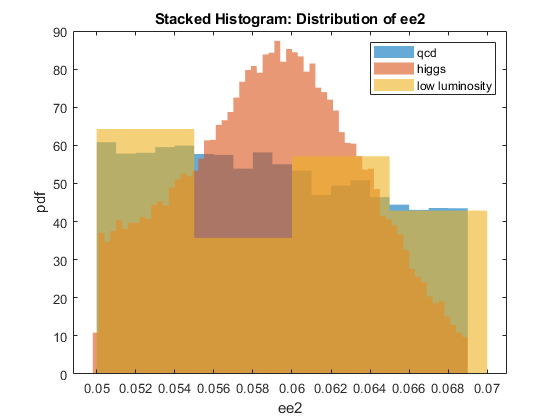

lee2=low(5,:);
lee2(lee2<=bot_cut2)=[];
lee2(lee2>top_cut2)=[];

qcd_ee2 = qcd_dataset(5,:);
qcd_ee2(qcd_ee2<=bot_cut2)=[];
qcd_ee2(qcd_ee2>top_cut2)=[];

higgs_ee2 = higgs_dataset(5,:);
higgs_ee2(higgs_ee2<=bot_cut2)=[];
higgs_ee2(higgs_ee2>top_cut2)=[];

figure;
histogram(qcd_ee2,"EdgeColor",'none',"Normalization","pdf");
hold on
histogram(higgs_ee2,"EdgeColor",'none',"Normalization","pdf");
histogram(lee2,"EdgeColor",'none',"Normalization","pdf");
legend('qcd','higgs','low luminosity')
title('Stacked Histogram: Distribution of ee2')
ylabel('pdf')
xlabel('ee2')

- 95% Confidence Level of signal yields

- In the low luminosity data, the observed significance is less than 5σσ. We will calculate the 95% confidence level upper limit of signal yield.

- Evaluate the expected 95% confidence level upper limit

- Evaluate the observed 95% confidence level upper limit

- Compare expectation to observation. Comment on your finding.